### Test CBF manipolatore due bracci

clc
clear
close all

Controllo 100Hz:

dt = 0.01;

Condizioni iniziali:

q   = [0.5; 0.5]*(pi/2);
dq  = [0; 0];
ddq = [0; 0];

Parametri manipolatore:

%params = [m1, a1, l1, I1, m2, a2, l2, I2];
params = [1, 1, 0.5, 1, 1, 1, 0.5, 1]; 

q_des = [0.1; 0.1];
kp = 20;                                               
kd = 2*sqrt(kp);
q_cr = [0; 0];
plot_data.q = q;
plot_data.dq = dq;

for i = 1:1500
    % Nominal control input
    e = q_des - q;
    [B, C, g] = get_dynamics(q,dq,params);
    n = C*dq;
    tau= kp*e - kd*dq;            %de = dq_des - dq ma dq_des = 0
    v = computed_torque_control(dq,tau,B,C,g) - g;
    
    % Control Barrier Function constraints
    invB = pinv(B);
    F = -invB*C*dq;
    B0 = F + dq + diag([1,1])*(q-q_cr);
    
    Q = eye(2);
    p = -v;

    G = -invB;
    h = B0;
    
    u = quadprog(Q, p, G, h, ...
        [], [], [], [], [], optimoptions('quadprog','Display','off'));
    
    % Integration step
    ddq = pinv(B)*(u-n);
    dq  = dq + ddq*dt;
    q   = q + dq*dt;
    
    plot_data.q = [plot_data.q, q];
    plot_data.dq = [plot_data.dq, dq];
end
q

q =     0.1000
    0.1000


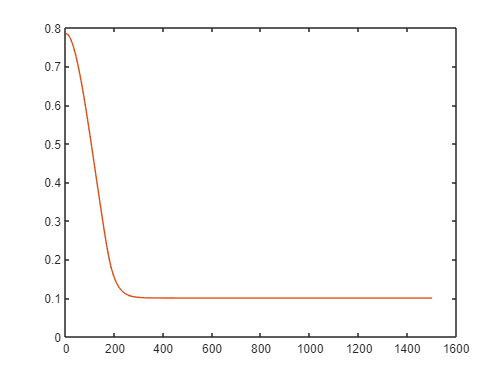

figure
plot(plot_data.q')